# Lab A Report

## Task 4.1 - Linearized EOM in State Space (SS) form

Equations of Motion:

    
$$m_b l_b \ddot{x}_w + (I_b + m_b l_b^2)\ddot{\theta}_b = m_b l_b g \theta_b + \left( \frac{2 K_e K_t}{R_m} + b_f \right)\left( \frac{\dot{x}_w}{l_w} + \dot{\theta}_b \right)  - \frac{2 K_t}{R_m}v_m$$


    
$$(\frac{I_w}{l_w} + l_w m_b + l_w m_w)\ddot{x}_w + m_b l_b l_w \ddot{\theta}_b =  - \left( \frac{2 K_e K_t}{R_m} + b_f \right)\left( \frac{\dot{x}_w}{l_w} + \dot{\theta}_b \right) + \frac{2 K_t}{R_m}v_m$$


In the form:


$$\dot{x} = Ax + Bu$$



$$y = Cx + Du$$


syms g b_f m_b l_b I_b m_w l_w I_w R_m L_m b_m K_e K_t
syms x_w theta_b v_m 

A = sym('A_%d%d', [4 4]);
B = sym('B_%d%d', [4 1]);
C = sym('C_%d%d', [1 4]);
D = sym('D_%d%d', [1 1]);

Alpha = sym('alpha_%d%d', [4 4]);
Beta = sym('beta_%d%d', [4 1]);
Gamma = sym('gamma_%d%d', [4 4]);

Alpha(:,:) = 0;
Alpha(1,2) = 1;
Alpha(2,2) = ((2*K_e*K_t)/(R_m*l_w)) + (b_f/l_w);
Alpha(2,3) = m_b*l_b*g;
Alpha(2,4) = -((2*K_e*K_t)/R_m) - b_f;
Alpha(3,4) = 1;
Alpha(4,2) = -((2*K_e*K_t)/(R_m*l_w)) - (b_f/l_w);
Alpha(4,4) = ((2*K_e*K_t)/R_m) + b_f;
Alpha

$$Alpha = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & \frac{b_{f}}{l_{w}}+\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}} & g\,l_{b}\,m_{b} & -b_{f}-\frac{2\,K_{e}\,K_{t}}{R_{m}}\\ 0 & 0 & 0 & 1\\ 0 & -\frac{b_{f}}{l_{w}}-\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}} & 0 & b_{f}+\frac{2\,K_{e}\,K_{t}}{R_{m}} \end{array}\right)$$




Beta(:,:) = 0;
Beta(2,1) = -2*K_t/R_m;
Beta(4,1) = 2*K_t/R_m;
Beta

$$Beta = \left(\begin{array}{c} 0\\ -\frac{2\,K_{t}}{R_{m}}\\ 0\\ \frac{2\,K_{t}}{R_{m}} \end{array}\right)$$


Gamma(:,:) = 0;
Gamma(1,1) = 1;
Gamma(2,2) = m_b*l_b;
Gamma(2,4) = I_b + m_b*l_b^2;
Gamma(3,3) = 1;
Gamma(4,2) = (I_w/l_w) + l_w*m_b + l_w*m_w;
Gamma(4,4) = m_b * l_b * l_w;
Gamma

$$Gamma = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & l_{b}\,m_{b} & 0 & m_{b}\,{l_{b}}^{2}+I_{b}\\ 0 & 0 & 1 & 0\\ 0 & l_{w}\,m_{b}+l_{w}\,m_{w}+\frac{I_{w}}{l_{w}} & 0 & l_{b}\,l_{w}\,m_{b} \end{array}\right)$$



A = inv(Gamma)*Alpha

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{l_{w}\,\sigma_{5}\,\sigma_{2}}{\sigma_{1}}-\frac{l_{b}\,{l_{w}}^{2}\,m_{b}\,\sigma_{2}}{\sigma_{1}} & -\frac{g\,{l_{b}}^{2}\,{l_{w}}^{2}\,{m_{b}}^{2}}{\sigma_{1}} & \frac{l_{w}\,\sigma_{5}\,\sigma_{4}}{\sigma_{1}}+\frac{l_{b}\,{l_{w}}^{2}\,m_{b}\,\sigma_{4}}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{\sigma_{2}\,\sigma_{3}}{\sigma_{1}}+\frac{l_{b}\,l_{w}\,m_{b}\,\sigma_{2}}{\sigma_{1}} & \frac{g\,l_{b}\,m_{b}\,\sigma_{3}}{\sigma_{1}} & -\frac{\sigma_{4}\,\sigma_{3}}{\sigma_{1}}-\frac{l_{b}\,l_{w}\,m_{b}\,\sigma_{4}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{b}\,I_{w}+I_{b}\,{l_{w}}^{2}\,m_{b}+I_{w}\,{l_{b}}^{2}\,m_{b}+I_{b}\,{l_{w}}^{2}\,m_{w}+{l_{b}}^{2}\,{l_{w}}^{2}\,m_{b}\,m_{w}\\ \sigma_{2}=\frac{b_{f}}{l_{w}}+\frac{2\,K_{e}\,K_{t}}{R_{m}\,l_{w}}\\ \sigma_{3}=I_{w}+{l_{w}}^{2}\,m_{b}+{l_{w}}^{2}\,m_{w}\\ \sigma_{4}=b_{f}+\frac{2\,K_{e}\,K_{t}}{R_{m}}\\ \sigma_{5}=m_{b}\,{l_{b}}^{2}+I_{b} \end{array}$$

B = inv(Gamma)*Beta

$$B = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{2\,K_{t}\,l_{w}\,\left(m_{b}\,{l_{b}}^{2}+I_{b}\right)}{\sigma_{1}}+\frac{2\,K_{t}\,l_{b}\,{l_{w}}^{2}\,m_{b}}{\sigma_{1}}\\ 0\\ -\frac{2\,K_{t}\,\left(I_{w}+{l_{w}}^{2}\,m_{b}+{l_{w}}^{2}\,m_{w}\right)}{\sigma_{1}}-\frac{2\,K_{t}\,l_{b}\,l_{w}\,m_{b}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{m}\,\left(I_{b}\,I_{w}+I_{b}\,{l_{w}}^{2}\,m_{b}+I_{w}\,{l_{b}}^{2}\,m_{b}+I_{b}\,{l_{w}}^{2}\,m_{w}+{l_{b}}^{2}\,{l_{w}}^{2}\,m_{b}\,m_{w}\right) \end{array}$$

C = [0, 0, 1, 0]

C =      0     0     1     0


D = [0]

D = 0

### Subtitute Parameter Numerical Values


PARAMS = [g, b_f, m_b, l_b, I_b, m_w, l_w, I_w, R_m, L_m, b_m, K_e, K_t];
VALUES = [9.8, 0, 0.463, 0.113, 0.00767, 0.026, 0.021, 0.00000573, 4.4, 0, 0, 0.444, 0.47]; 

A_val = round(subs(A,PARAMS,VALUES),1)

$$A\_val = \left(\begin{array}{cccc} 0 & 1.0 & 0 & 0\\ 0 & -773.8 & -6.6 & 16.2\\ 0 & 0 & 0 & 1.0\\ 0 & 3313.2 & 63.1 & -69.6 \end{array}\right)$$

B_val = round(subs(B,PARAMS,VALUES),4)

$$B\_val = \left(\begin{array}{c} 0\\ 36.598\\ 0\\ -156.7072 \end{array}\right)$$

## Task 4.2 - Transfer Function of the LTI SS System

% to calculate with full acuracy
A_value = subs(A,PARAMS,VALUES);
B_value = subs(B,PARAMS,VALUES);
% Matrixes has to be first cast to doulbe to make command work correctly.
% Matlab handles the values infinit if they are not casted or other way
% handled
sys = ss(double(A_value),double(B_value  ),C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0  -773.8  -6.574   16.25
   x3       0       0       0       1
   x4       0    3313   63.07  -69.58
 
  B = 
           u1
   x1       0
   x2    36.6
   x3       0
   x4  -156.7
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% to plot zero/pole/gain model use
G = zpk(sys)

G =
 
            -156.71 s
  -----------------------------
  (s+843.4) (s+5.642) (s-5.679)
 
Continuous-time zero/pole/gain model.



% To plot pole-zero map
% pzplot(sys)
% To set only poles
poles = pole(sys)

poles =  -843.4002
   -5.6422
    5.6790
         0


% To get the transfer function
H_p = tf(sys)

H_p =
 
          -156.7 s - 2.11e-11
  ------------------------------------
  s^3 + 843.4 s^2 - 63.07 s - 2.702e04
 
Continuous-time transfer function.



isstable(sys)

ans = logical
   0


% rlocus(sys)
% step(sys)


Design 2nd Order System

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




M_p = 5 % Max overshoot in percent

M_p = 5

t_r = 0.01 % Rise Time 10-90 percent

t_r = 0.0100


zeta = 0.6*(1- (M_p/100))

zeta = 0.5700

omega_n = 1.8/t_r

omega_n = 180


H_cl = (omega_n^2)/(s^2 + 2*zeta*omega_n*s + omega_n^2)

H_cl =
 
          32400
  ---------------------
  s^2 + 205.2 s + 32400
 
Continuous-time transfer function.




isstable(H_cl)

ans = logical
   1



pole(H_cl)

ans = 	1.0e+02 *

  -1.0260 + 1.4790i
  -1.0260 - 1.4790i



H_pid = H_cl/(H_p*(1-H_cl))

H_pid =
 
  -32400 s^5 - 3.397e07 s^4 - 6.655e09 s^3 - 8.84e11 s^2 + 2.459e11 s + 2.837e13
  ------------------------------------------------------------------------------
       156.7 s^5 + 6.431e04 s^4 + 1.168e07 s^3 + 1.042e09 s^2 + 0.0001403 s
 
Continuous-time transfer function.




zpk(H_pid)

ans =
 
  -206.75 (s+843.4) (s+5.642) (s-5.679) (s^2 + 205.2s + 3.24e04)
  --------------------------------------------------------------
              s^2 (s+205.2) (s^2 + 205.2s + 3.24e04)
 
Continuous-time zero/pole/gain model.



p1 = 843.4

p1 = 843.4000

p2 = 5.642

p2 = 5.6420

K = -206.75

K = -206.7500

H_pid_s = K*(s-p1)*(s-p2)/s^2

H_pid_s =
 
  -206.8 s^2 + 1.755e05 s - 9.838e05
  ----------------------------------
                 s^2
 
Continuous-time transfer function.



Design PID Controller:

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




kP = 1

kP = 1

kI = 1

kI = 1

kD = 1

kD = 1


G_PID = kP + kI/s + kD*s

G_PID =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.



## Task 4.3 - PID Controller:

A = double(A_value)

A = 	1.0e+03 *

         0    0.0010         0         0
         0   -0.7738   -0.0066    0.0162
         0         0         0    0.0010
         0    3.3132    0.0631   -0.0696


B= double(B_value)

B =          0
   36.5980
         0
 -156.7072


E= eig(double(A_value))

E =          0
 -843.4002
   -5.6422
    5.6790


Desired Poles:

P= [0,-843.4002,-5.6422,-5.1]

P =          0 -843.4002   -5.6422   -5.1000


K= place(A, B, P)

K =     0.0000  -40.1299  -58.4008   -9.4409


Scaling Factor:

Acl= A-B*K

Acl = 	1.0e+03 *

         0    0.0010         0         0
   -0.0000    0.6949    2.1308    0.3618
         0         0         0    0.0010
    0.0000   -2.9754   -9.0887   -1.5490


Ecl= eig(Acl)

Ecl =  -843.4002
    0.0000
   -5.6422
   -5.1000


Step Response:

syscl= ss(Acl, B, C, D)

syscl =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2  -1.667e-14       694.9        2131       361.8
   x3           0           0           0           1
   x4   7.136e-14       -2975       -9089       -1549
 
  B = 
           u1
   x1       0
   x2    36.6
   x3       0
   x4  -156.7
 
  C = 
       x1  x2  x3  x4
   y1   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



isstable(syscl)

ans = logical
   0


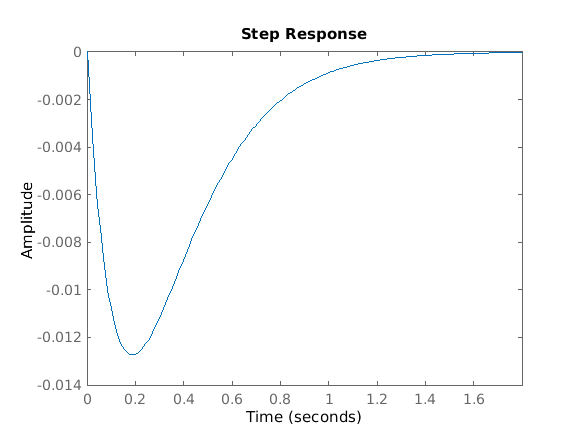

step(syscl)

[wn, zeta]= damp(syscl)

wn =     0.0000
    5.1000
    5.6422
  843.4002


zeta =     -1
     1
     1
     1


tr=1.8/wn

tr =          0         0         0    0.0021


zeta=1;
mp= exp(-pi*zeta/sqrt(1-pow2(zeta,2)))

mp = -0.2406 + 0.9706i

zpk(syscl)

ans =
 
           -156.71 s^2
  -----------------------------
  s (s+843.4) (s+5.642) (s+5.1)
 
Continuous-time zero/pole/gain model.



tf(syscl)

ans =
 
         -156.7 s^2 - 9.494e-12 s + 4.468e-36
  ---------------------------------------------------
  s^4 + 854.1 s^3 + 9089 s^2 + 2.427e04 s - 9.198e-10
 
Continuous-time transfer function.



Kdc= dcgain(syscl)

Kdc = 1.8299e-16

Kr= 1/Kdc

Kr = 5.4648e+15

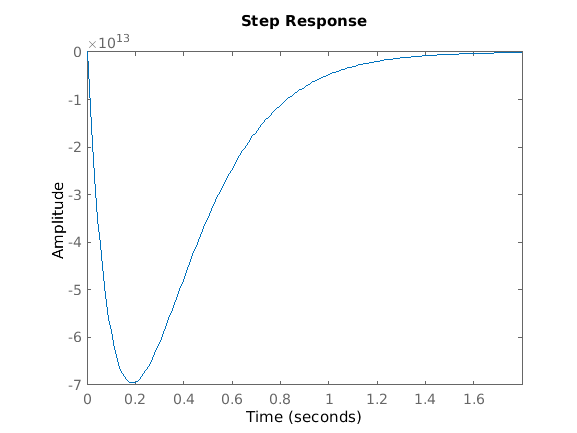

syscl_scaled= ss(Acl, B*Kr, C, D);
step(syscl_scaled)

dcScl= dcgain(syscl_scaled)

dcScl = 3.8899

isstable(syscl_scaled)

ans = logical
   0


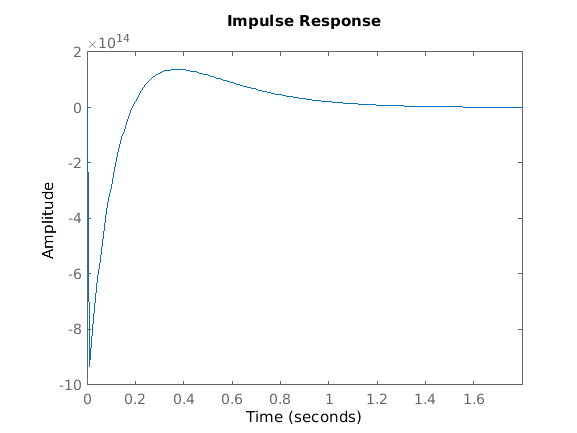

impulse(syscl_scaled)

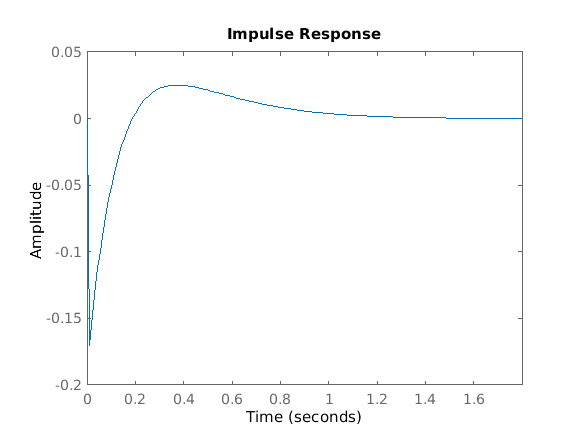

impulse(syscl)

## Task 4.3 - Design PID controller 

P(s)= (K_p + K_i / s +k_d * s) 

H(s)=(P(s)*K(s))/(1+P(s)*K(s))

%p1=-843.4002
%p2=-5.6422
%then we select p3 to negative real side so this time to -5
%p3=-5
%K=-156.71

syms s Kp Ki Kd p1 p2 p3 K
Ps=K*s/((s-p1)*(s-p2)*(s-p3))

$$Ps = -\frac{K\,s}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$


Ks=(Kp+Ki/s+Kd*s)

$$Ks = \mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}$$


$$\textrm{Ks}=\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}$$




% The closed loop system with PID and proces

Hs=(Ps*Ks)/(1+Ps*Ks)

$$Hs = \frac{K\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)\,\left(\frac{K\,s\,\left(\mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}-1\right)}$$


$$\frac{K\,s\,{\left(\textrm{Ki}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{{\left(p_1 -s\right)}\,{\left(p_2 -s\right)}\,{\left(p_3 -s\right)}\,{\left(\frac{K\,s\,{\left(\textrm{Ki}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{{\left(p_1 -s\right)}\,{\left(p_2 -s\right)}\,{\left(p_3 -s\right)}}-1\right)}}$$


p1=-843.4002

p1 = -843.4002

p2=-5.6422

p2 = -5.6422

%then we select p3 to negative real side so this time to -5
p3=-5

p3 = -5

% K=-156.71
% Ps=K*s/((s-p1)*(s-p2)*(s-p3))
% Ks=(Kp+Ki/s+Kd*s)
% Hs=(Ps*Ks)/(1+Ps*Ks)


$$\frac{15671\,s\,{\left(\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{100\,{\left(s+\frac{231832081692151}{274877906944}\right)}\,{\left(\frac{15671\,s\,{\left(\textrm{Kp}+\textrm{Kd}\,s+\frac{\textrm{Ki}}{s}\right)}}{100\,{\left(s+\frac{231832081692151}{274877906944}\right)}\,{\left(s+5\right)}\,{\left(s+\frac{28211}{5000}\right)}}-1\right)}\,{\left(s+5\right)}\,{\left(s+\frac{28211}{5000}\right)}}$$


Earlier values from PID tuner were

kp -355.5263

ki 1.0256e+04

kd -1.2450

But al poles did not go to the correct

Another PID tuner values 

kp -558.3481

ki -13776.6318

kd -0.87072

## Task 4.3 - Design PID controller 


$$G_{PID}(s)= K_p + \frac{K_i} {s} +\frac{K_ds}{1+\frac{K_ds}{N}}$$
 

H(s)=(P(s)*K(s))/(1+P(s)*K(s))

syms s K_p K_i K_d p_1 p_2 p_3 K N
P_s=K*s/((s-p_1)*(s-p_2)*(s-p_3))

$$P\_s = -\frac{K\,s}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$

K_s=K_p+K_i/s+(K_d*s/(1+(K_d*s/N)))

$$K\_s = K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}$$

H_cl=(P_s*K_s)/(1+P_s*K_s)

$$H\_cl = \frac{K\,s\,\left(K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}\right)}{\left(\frac{K\,s\,\left(K_{p}+\frac{K_{i}}{s}+\frac{K_{d}\,s}{\frac{K_{d}\,s}{N}+1}\right)}{\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}-1\right)\,\left(p_{1}-s\right)\,\left(p_{2}-s\right)\,\left(p_{3}-s\right)}$$


poles

poles =  -843.4002
   -5.6422
    5.6790
         0



p1=-843.4002

p1 = -843.4002

p2=-5.6422

p2 = -5.6422

%then we select p3 to negative real side so this time to -5
p3=-5

p3 = -5

K=-156.71

K = -156.7100

Ps=tf(sys)

Ps =
 
          -156.7 s - 2.11e-11
  ------------------------------------
  s^3 + 843.4 s^2 - 63.07 s - 2.702e04
 
Continuous-time transfer function.



Ks=pid(K,K,K)

Ks =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -157, Ki = -157, Kd = -157
 
Continuous-time PID controller in parallel form.



Hs=(Ps*Ks)/(1+Ps*Ks)

Hs =
 
     2.456e04 s^7 + 2.074e07 s^6 + 1.919e07 s^5 - 6.445e08 s^4 - 6.652e08 s^3 - 6.637e08 s^2 - 8.934e-05 s
  -----------------------------------------------------------------------------------------------------------
  s^8 + 2.624e04 s^7 + 2.145e07 s^6 + 1.903e07 s^5 - 6.901e08 s^4 - 6.618e08 s^3 + 6.667e07 s^2 - 8.934e-05 s
 
Continuous-time transfer function.



simplify(Hs)

ans =
 
     2.456e04 s^7 + 2.074e07 s^6 + 1.919e07 s^5 - 6.445e08 s^4 - 6.652e08 s^3 - 6.637e08 s^2 - 8.934e-05 s
  -----------------------------------------------------------------------------------------------------------
  s^8 + 2.624e04 s^7 + 2.145e07 s^6 + 1.903e07 s^5 - 6.901e08 s^4 - 6.618e08 s^3 + 6.667e07 s^2 - 8.934e-05 s
 
Continuous-time transfer function.



## Task 4.6 - Discretize TF - C(z)

% ComputePIDGains;
% sys_pid = pid(kP,kI,kD)
% Ts = 0.2
% % sys_d_pid = c2d(sys_pid,Ts)
% isstable(sys_d_pid)
% step(sys_d_pid)